# Signal Processing with MATLAB

*This lecture is partly adapted from MATLAB online tutorial.*

## Signal Processing Toolbox

[https://www.mathworks.com/products/signal.html](https://www.mathworks.com/products/signal.html)

Signal Processing Toolbox™ provides functions and apps to analyze, preprocess, and extract features from uniformly and nonuniformly sampled signals. 

It provides tools and algorithms for:

- filter design and analysis

- resampling, smoothing, detrending

- power spectrum estimation

- extracting features like changepoints and envelopes

- finding peaks and signal patterns

- quantifying signal similarities

- performing measurements such as SNR and distortion

- ... ...

### Signal processing pipeline

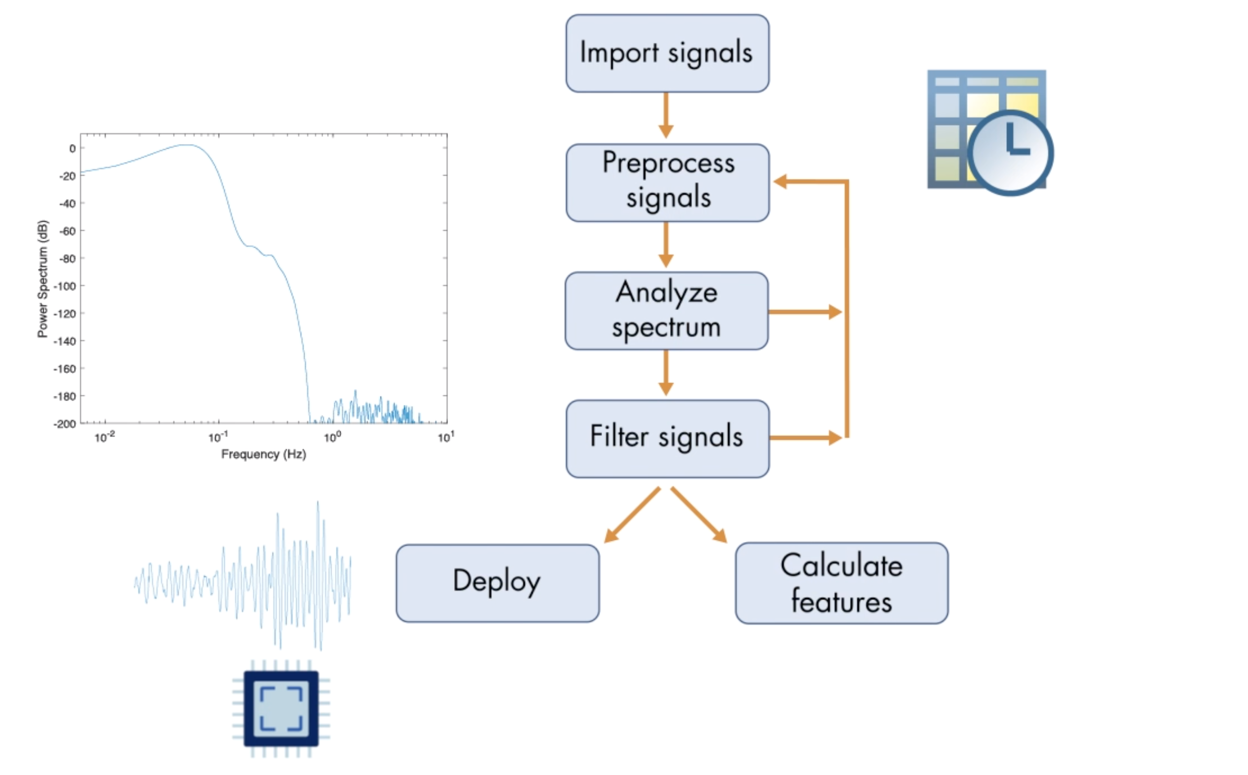

## Signal processing methods for spectral analysis

**Earthquak data (December 26, 2004, Indonesia)**

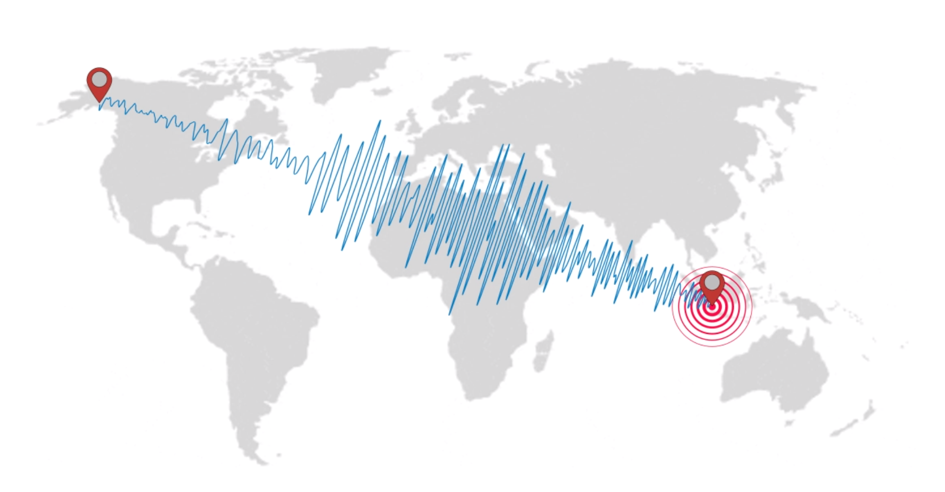

The vibrations travel all the way to Alaska, and are picked up by three seismic stations.

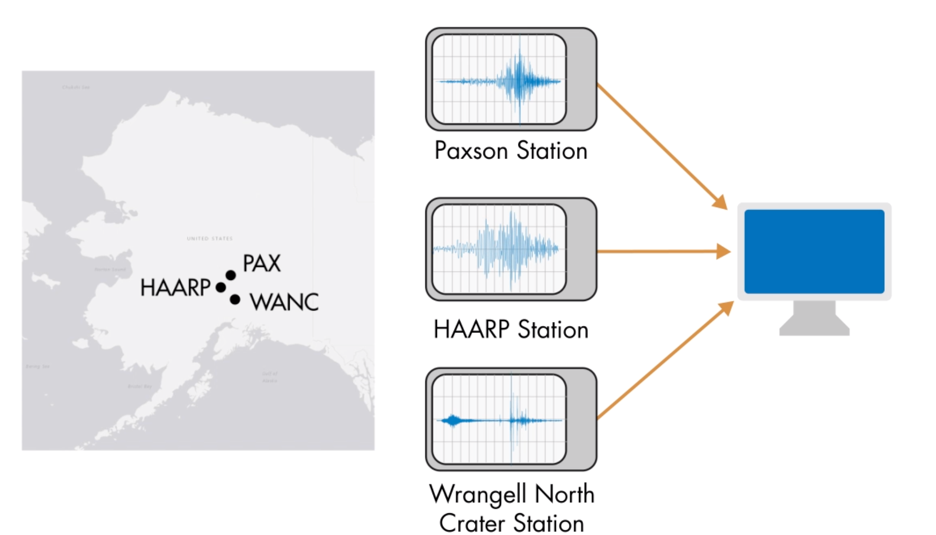

### Load and display signals

Ts = readmatrix("data/seismicstation_ts.csv");
harp = readtimetable("data/harp.csv","SampleRate",1/Ts(1));
plot(harp.Time,harp.Signal)

### Basic preprocessing 

Initial preprocessing could include:

- Normalizing

- Resampling

- Aligning

Extract a region of the HARP signal.

tstart = seconds(2000);
tend = seconds(4000);
timeLimits = timerange(tstart,tend);
harp = harp(timeLimits,:);
plot(harp.Time,harp.Signal)

### Power spectrum

View the frequency content of a signal by calculating the power spectrum with the `pspectrum` function.

pspectrum(harp)

Zoom in on the meaningful seismic activity by setting the frequency limits while calculating the power spectrum.

pspectrum(harp,"FrequencyLimits",[0 1])

### Compare signals

Compare the seismic signals from the HARP, PAX, and Mt Wrangell stations.

harp = readtimetable("data/harp.csv","SampleRate",1/Ts(1));
pax = readtimetable("data/pax.csv","SampleRate",1/Ts(2));
wanc = readtimetable("data/wanc.csv","SampleRate",1/Ts(3));

subplot(3,1,1)
plot(harp.Time,harp.Signal)
title("HARP")

subplot(3,1,2)
plot(pax.Time,pax.Signal)
title("PAX")

subplot(3,1,3)
plot(wanc.Time,wanc.Signal)
title("WANC")

Compare the frequency content.

quakes = synchronize(harp,pax);
head(quakes)
head(wanc)
figure
pspectrum(quakes,"FrequencyLimits",[0 1])
legend(quakes.Properties.VariableNames)

### Cleaning up signals

Resample `wanc` to match the sample rate for `harp` and `pax`.

The seismic signals are all uniformly sampled, so here we only need to provide the signal and resample factors, `p` and `q`. 

`y` `=` `resample``(``x``,``p``,``q``)`

`p` and `q` are integer resample factors. The output signal `y` has `p/q` samples from `x`.

wanc = resample(table2array(wanc),1,2);
wanc = array2timetable(wanc,'SampleRate',1/Ts(3)*1/2,'VariableNames',{'Signal'})

quakes = synchronize(harp,pax,wanc);
stackedplot(quakes);

The HARP and PAX signals are much larger than the Mount Wrangell signal. It will be easier to compare the signals if they're all normalized. 

harp = normalize(harp);
pax = normalize(pax);
wanc = normalize(wanc);
quakes = synchronize(harp,pax,wanc);

figure
pspectrum(quakes,"FrequencyLimits",[0 1])
legend(quakes.Properties.VariableNames);

### Aligning signals

The seismic stations are located in different places in Alaska. As the surface waves traveled from Indonesia, they arrived at the seismic stations at different times. The distance between stations caused a lag between the recorded waves.

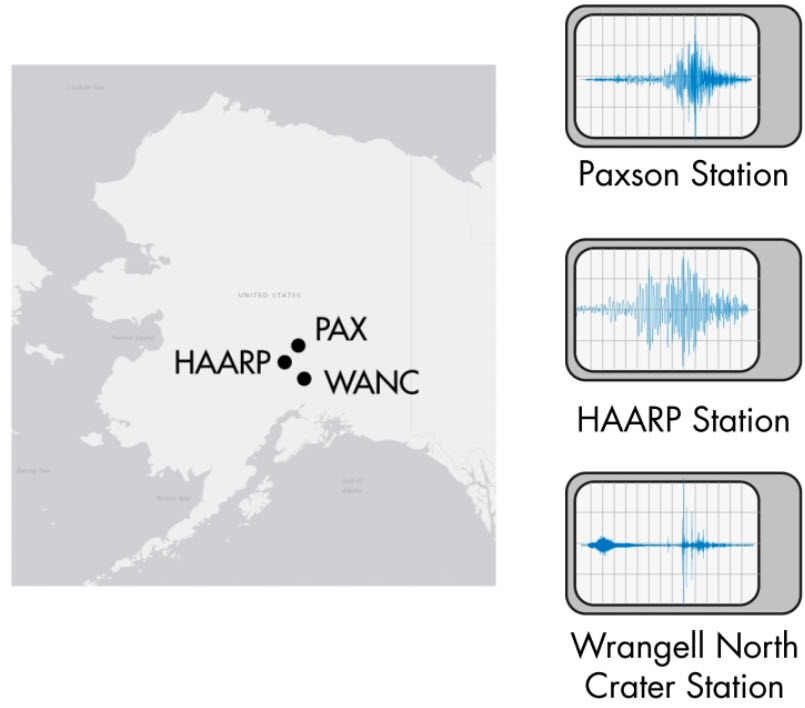

clf
plot(harp.Time,harp.Signal)
hold on
plot(pax.Time,pax.Signal)
hold off
legend("HARP","PAX")
xlim(seconds([2800 3500]))

**Cross-correlation** can be used to measure the similarity between a signal and a shifted, or lagged, copy of that signal. Even though the HARP, PAX, and Mount Wrangell signals aren't copies of each other, all three seismometers should have picked up the same surface waves from the Sumatra earthquake.

Visualize cross-correlation using stem plots.

[c,lags] = xcorr(harp.Signal,wanc.Signal);
stem(lags,c)

The `finddelay` function uses cross-correlation to estimate the **delay** between signals. The output `harpDelay` is the number of lagged samples, can be multiplied with the time step to get the number of seconds.

harpDelay = seconds(finddelay(harp.Signal,wanc.Signal)*Ts(1))
paxDelay = seconds(finddelay(pax.Signal,wanc.Signal)*Ts(2))

Modify the timetables to align them by setting the `StartTime` property of the timetable. 

harp.Properties.StartTime = harpDelay;
pax.Properties.StartTime = paxDelay;

View the aligned signals

plot(harp.Time,harp.Signal)
hold on
plot(pax.Time,pax.Signal)
hold on
plot(wanc.Time,wanc.Signal)
hold off
legend("HARP","PAX","WANC")
xlim(seconds([2800 3500]))

plot(harp.Time,harp.Signal)
hold on
plot(pax.Time,pax.Signal)
hold off
legend("HARP","PAX")
xlim(seconds([2800 3500]))

### **Spectral Analysis**

A dB scale is usually used to visualize power spectrums by calculating `10*log10(p)`, where *p* is the spectrum.

[p,f] = pspectrum(quakes);
semilogx(f,db(p,"power"))
legend("HARP","PAX","WANC")
xlabel("Frequency (Hz)")
ylabel("Power Spectrum (dB)")

Create a spectrogram with the `pspectrum` function by including the input `"spectrogram"`. 

pspectrum(quakes.Signal_wanc,quakes.Time,"spectrogram")

Most tremors from local earthquakes contain frequencies between 2 Hz and 10 Hz. Remove frequencies that have low power using the `"MinThreshold"` option.

pspectrum(quakes.Signal_wanc,quakes.Time,"spectrogram",...
    "FrequencyLimits",[2 10],"MinThreshold",-50)

### Filtering

**Lowpass Filter**

The low frequencies and the high frequencies correspond to two different seismic events. We can extract the low frequency surface waves from the Indonesian earthquake and the seismic activity that it caused in Alaska.

Lowpass filter the Mount Wrangell signal at `0.1` Hz.

lowpass(quakes(:,"Signal_wanc"),0.1,"Steepness",0.95);

lowWANC = lowpass(quakes(:,"Signal_wanc"),0.1,"Steepness",0.95);
quakes.FiltWANC = lowWANC.Signal_wanc;
figure
stackedplot(quakes)

**Bandpass Filter**

Get the high frequency content, which corresponds to the local earthquakes near Mount Wrangell. The frequency range of local earthquakes is 2 Hz to 10 Hz.

bandWANC = bandpass(quakes(:,"Signal_wanc"),[2 10]);
compfilt = timetable(bandWANC.Time,bandWANC.Signal_wanc,...
    quakes.FiltWANC,'VariableNames',["Bandpass" "Lowpass"]);
figure
stackedplot(compfilt);
xlim([seconds(2900) seconds(2950)])

The earth scientists thought that the earthquake in Sumatra triggered the earthquakes in Alaska. Using filtering, they were able to compare the low frequency and high frequency signals from the Mount Wrangell seismometer. This provided a rare opportunity for them to confirm the relationship between two distant earthquakes.

close all; clear; clc

## Audio Toolbox

[https://www.mathworks.com/products/audio.html](https://www.mathworks.com/products/audio.html)

Audio Toolbox™ provides tools for audio processing, speech analysis, and acoustic measurement. 

It provides tools and algorithms for:

- processing audio signals such as equalization and time stretching 

- estimating acoustic signal metrics such as loudness and sharpness 

- extracting audio features such as MFCC and pitch

- advanced machine learning models, including i-vectors

- pretrained deep learning networks, including VGGish and CREPE

- live algorithm testing

- impulse response measurement

- signal labeling

- ... ...

*The following lecture material is taken from *[*MATLAB examples*](https://www.mathworks.com/help/examples.html)*.*

## Speaker Identification 

A machine learning approach to identify people based on features extracted from recorded speech.

The features used to train the classifier are the **pitch** of the voiced segments of the speech and the **mel frequency cepstrum coefficients (MFCC)**. 

This example uses the Census Database (also known as AN4 Database) from the CMU Robust Speech Recognition Group [[1](https://www.mathworks.com/help/audio/ug/speaker-identification-using-pitch-and-mfcc.html#mw_rtc_SpeakerIdentificationUsingPitchAndMFCCExample_55DB515C)]. The data set contains recordings of male and female subjects speaking words and numbers. The helper function in this section downloads it for you and converts the raw files to FLAC. The speech files are partitioned into subdirectories based on the labels corresponding to the speakers. If you are unable to download it, you can load a table of features from `HelperAN4TrainingFeatures.mat` and proceed directly to the **Training a Classifier** section. The features have been extracted from the same data set.

addpath("data/SpeakerIdentificationUsingPitchAndMFCCExample/")
dataDir = HelperAN4Download;

Create an `audioDatastore` object to easily manage this database for training. The datastore allows you to collect necessary files of a file format and read them.

ads = audioDatastore(dataDir,'IncludeSubfolders',true, ...
    'FileExtensions','.flac', ...
    'LabelSource','foldernames')

[adsTrain, adsTest] = splitEachLabel(ads,0.8);
trainDatastoreCount = countEachLabel(adsTrain)
testDatastoreCount = countEachLabel(adsTest)

Preview the content of your datastore

[sampleTrain, dsInfo] = read(adsTrain);
sound(sampleTrain,dsInfo.SampleRate)
reset(adsTrain)

#### **Feature Extraction**

Extract pitch and MFCC features from each frame that corresponds to voiced speech in the training datastore. 

fs = dsInfo.SampleRate;
windowLength = round(0.03*fs);
overlapLength = round(0.025*fs);

features = [];
labels = [];
while hasdata(adsTrain)
    [audioIn,dsInfo] = read(adsTrain);
    
    melC = mfcc(audioIn,fs,'WindowLength',windowLength,'OverlapLength',overlapLength);
    f0 = pitch(audioIn,fs,'WindowLength',windowLength,'OverlapLength',overlapLength);
    feat = [melC,f0];
    
    voicedSpeech = isVoicedSpeech(audioIn,fs,windowLength,overlapLength);
    
    feat(~voicedSpeech,:) = [];
    label = repelem(dsInfo.Label,size(feat,1));
    
    features = [features;feat];
    labels = [labels,label];
end

Normalize the features by subtracting the mean and dividing the standard deviation.

M = mean(features,1);
S = std(features,[],1);
features = (features-M)./S;

#### **Training a Classifier**

trainedClassifier = fitcknn( ...
    features, ...
    labels, ...
    'Distance','euclidean', ...
    'NumNeighbors',5, ...
    'DistanceWeight','squaredinverse', ...
    'Standardize',false, ...
    'ClassNames',unique(labels));

k = 5;
group = labels;
c = cvpartition(group,'KFold',k); % 5-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,'CVPartition',c);

Compute the validation accuracy and visualize the confusion chart.

validationAccuracy = 1 - kfoldLoss(partitionedModel,'LossFun','ClassifError');
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);
validationPredictions = kfoldPredict(partitionedModel);
figure
cm = confusionchart(labels,validationPredictions,'title','Validation Accuracy');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

#### **Testing the Classifier**

Test the trained KNN classifier with speech signals from each of the 10 speakers to see how well it behaves with signals that were not used to train it.

reset(adsTest)
features = [];
labels = [];
numVectorsPerFile = [];
while hasdata(adsTest)
    [audioIn,dsInfo] = read(adsTest);
    
    melC = mfcc(audioIn,fs,'WindowLength',windowLength,'OverlapLength',overlapLength);
    f0 = pitch(audioIn,fs,'WindowLength',windowLength,'OverlapLength',overlapLength);
    feat = [melC,f0];
    
    voicedSpeech = isVoicedSpeech(audioIn,fs,windowLength,overlapLength);
    
    feat(~voicedSpeech,:) = [];
    numVec = size(feat,1);
    
    label = repelem(dsInfo.Label,numVec);
    
    numVectorsPerFile = [numVectorsPerFile,numVec];
    features = [features;feat];
    labels = [labels,label];
end
features = (features-M)./S;

prediction = predict(trainedClassifier,features);
prediction = categorical(string(prediction));

figure('Units','normalized','Position',[0.4 0.4 0.4 0.4])
cm = confusionchart(labels,prediction,'title','Test Accuracy (Per Frame)');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

For a given file, predictions are made for every frame. Determine the mode of predictions for each file and then plot the confusion chart.

r2 = prediction(1:numel(adsTest.Files));
idx = 1;
for ii = 1:numel(adsTest.Files)
    r2(ii) = mode(prediction(idx:idx+numVectorsPerFile(ii)-1));
    idx = idx + numVectorsPerFile(ii);
end

figure('Units','normalized','Position',[0.4 0.4 0.4 0.4])
cm = confusionchart(adsTest.Labels,r2,'title','Test Accuracy (Per File)');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

close all; clear; clc

## DSP System Toolbox

[https://www.mathworks.com/products/dsp-system.html](https://www.mathworks.com/products/dsp-system.html)

DSP System Toolbox™ provides algorithms, apps, and scopes for designing, simulating, and analyzing signal processing systems in MATLAB and Simulink.

It provides tools and algorithms for:

- design and analyze FIR, IIR, multirate, multistage, and adaptive filters

- stream signals from variables, data files, and network devices for system development and verification

- dynamically visualize and measure streaming signals using the Time Scope, Spectrum Analyzer, and Logic Analyzer

- support C/C++ code generation for desktop prototyping and deployment to embedded processors

- support bit-accurate fixed-point modeling and HDL code generation from filters, FFT, IFFT, and other algorithm

- ... ...

#### **Visualize signals in frequency domain**

The **Spectrum Analyzer** System object displays the frequency spectrum of time-domain signals. This scope supports variable-size input, which allows the input frame size to change. Frame size is the first dimension of the input vector. The number of input channels must remain constant.

- Create the `dsp.SpectrumAnalyzer `object and call the object with arguments to display the spectra of signals in the Spectrum Analyzer.

- Set the `NumInputPorts` property to display multiple signals.

- `scope(signal1,signal2,...)` displays multiple signals in the spectrum analyzer. The signals must have the same frame length, but can vary in number of channels.

- Release system resources of a System object named `obj by` `release(obj).`

The right side of the spectrum analyzer shows the measurement panes (if enabled). The values shown in these panes match with the values shown in the last time step of the `data` variable. You can access the individual fields of `data` to obtain the various measurements programmatically.

Create a sine wave with a frequency of 100 Hz sampled at 1000 Hz, and another with a frequency of 240 Hz.

SampPerFrame = 1000;
Fs = 1000;
SW1 = dsp.SineWave('Frequency',100,'SampleRate',Fs,...
  'SamplesPerFrame',SampPerFrame);
SW2 = dsp.SineWave('Frequency',240,'SampleRate',Fs,...
  'SamplesPerFrame',SampPerFrame);

Generate ten seconds of the two sine waves with additive white noise in one-second intervals. Send the signals to a time scope and spectrum analyzer for display and measurement.

scope = dsp.SpectrumAnalyzer('NumInputPorts',2,'SampleRate',Fs);
tic;
while toc < 10
  sigData1 = SW1() + 0.05*randn(SampPerFrame,1);
  sigData2 = SW2() + 0.05*randn(SampPerFrame,1);
  scope(sigData1,sigData2);
end
release(scope)

Save the spectrum estimation displayed on a spectrum analyzer.

specTable = getSpectrumData(scope)

**Supporting Functions**

function voicedSpeech = isVoicedSpeech(x,fs,windowLength,overlapLength)

pwrThreshold = -40;
[segments,~] = buffer(x,windowLength,overlapLength,'nodelay');
pwr = pow2db(var(segments));
isSpeech = (pwr > pwrThreshold);

zcrThreshold = 1000;
zeroLoc = (x==0);
crossedZero = logical([0;diff(sign(x))]);
crossedZero(zeroLoc) = false;
[crossedZeroBuffered,~] = buffer(crossedZero,windowLength,overlapLength,'nodelay');
zcr = (sum(crossedZeroBuffered,1)*fs)/(2*windowLength);
isVoiced = (zcr < zcrThreshold);

voicedSpeech = isSpeech & isVoiced;

end